Loads protein/eve2 traces (run from src)

trace_struct_final1 = load('../dat/Kruppel_eve2_C/inference_traces_Kruppel_eve2_C_dT20.mat', 'trace_struct_final');
trace_struct_final1 = trace_struct_final1.trace_struct_final;

trace_struct_final2 = load('../dat/Kruppel_eve2_A/inference_traces_Kruppel_eve2_A_dT20.mat', 'trace_struct_final');
trace_struct_final2 = trace_struct_final2.trace_struct_final;

trace_struct_final = [trace_struct_final1 trace_struct_final2];

CompiledNuclei1 = load('../dat/Kruppel_eve2_C/2017-11-13-KrCRISPR_eve2_C_01/CompiledNuclei.mat', 'CompiledNuclei');
CompiledNuclei1 = CompiledNuclei1.CompiledNuclei;

CompiledNuclei2 = load('../dat/Kruppel_eve2_A/2017-11-12-KrCRISPR_eve2_A_01/CompiledNuclei.mat', 'CompiledNuclei');
CompiledNuclei2 = CompiledNuclei2.CompiledNuclei;

CompiledNuclei = [CompiledNuclei1 CompiledNuclei2];

View trace i

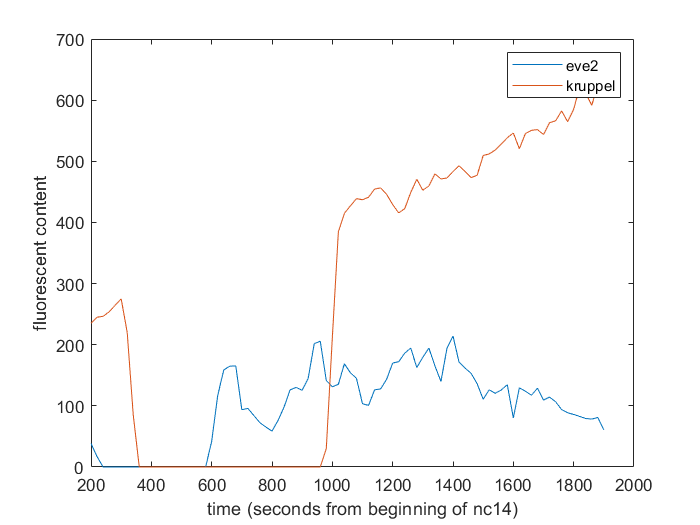

i = 147;
figure();
times = trace_struct_final(i).time_interp;
plot(times, trace_struct_final(i).fluo_interp)
hold on
plot(times, trace_struct_final(i).protein_interp)
legend('eve2', 'kruppel');
xlabel('time (seconds from beginning of nc14)');
ylabel('fluorescent content');

Compute Cross Correlation

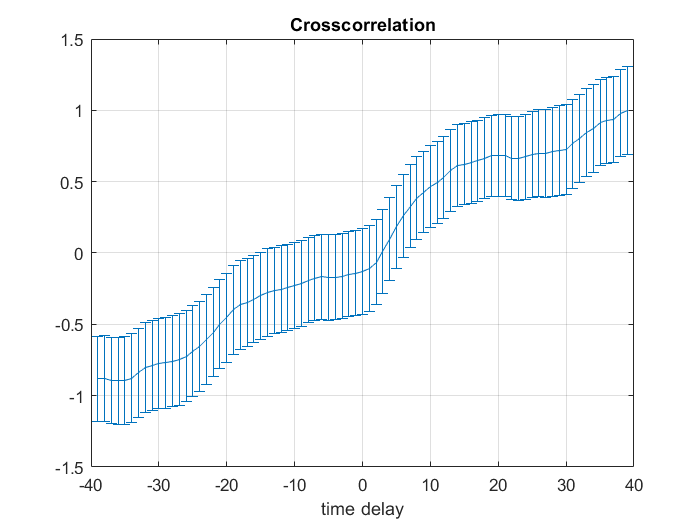

addpath('utilities/');
traces = cell(1,1);
proteins = cell(1,1);
k = 1;
for j = 1:length(trace_struct_final)
    if length(trace_struct_final(j).fluo_interp) > 40
        traces{k} = trace_struct_final(j).fluo_interp;
        proteins{k} = trace_struct_final(j).protein_interp;
        k = k + 1;
    end
end
max_delay = 40;
corr = cross_corr_m_calc(traces, proteins, max_delay);
deriv1 = corr(2:end) - corr(1:end-1);
deriv2 = deriv1(2:end) - deriv1(1:end-1);
[stds, stds1, stds2] = corr_bootstraps(traces,proteins,max_delay,150,'m');


figure();
%plot(-max_delay + 1:max_delay - 1, corr)
errorbar(-max_delay + 1:max_delay - 1, corr, stds);
title('Crosscorrelation')
xlabel('time delay')
grid on

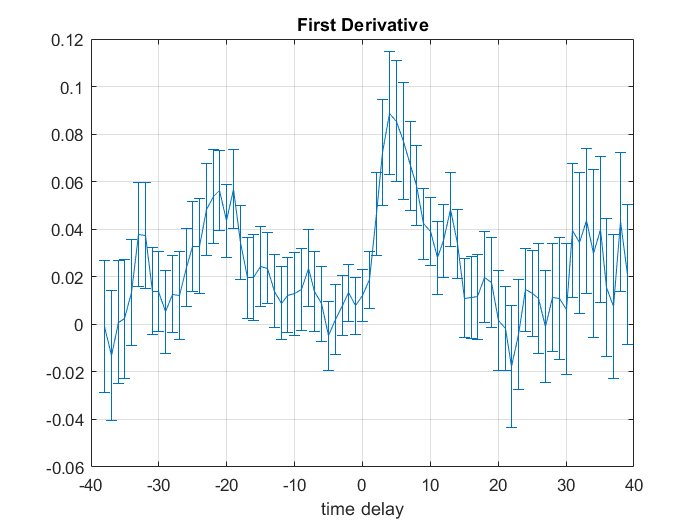


figure();
%plot(-max_delay + 2: max_delay - 1, deriv1);
errorbar(-max_delay + 2: max_delay - 1, deriv1, stds1);
title('First Derivative');
xlabel('time delay')
grid on

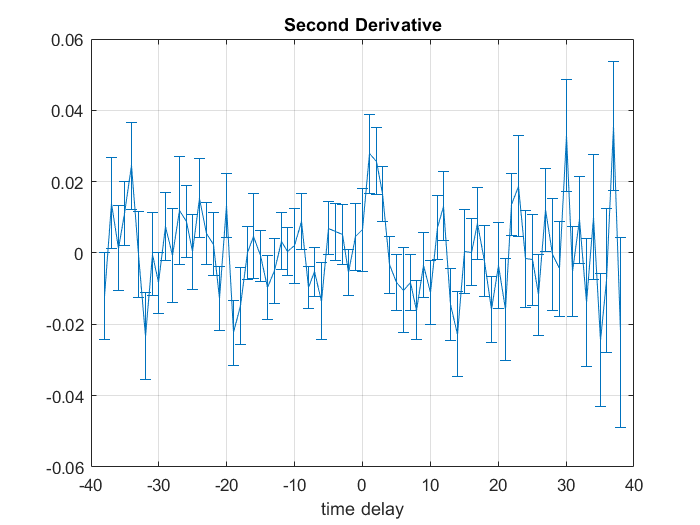


figure();
%plot(-max_delay + 2: max_delay - 2, deriv2);
errorbar(-max_delay + 2: max_delay - 2, deriv2, stds2);
title('Second Derivative');
xlabel('time delay')
grid on

Find average eve2 per Kruppel bin

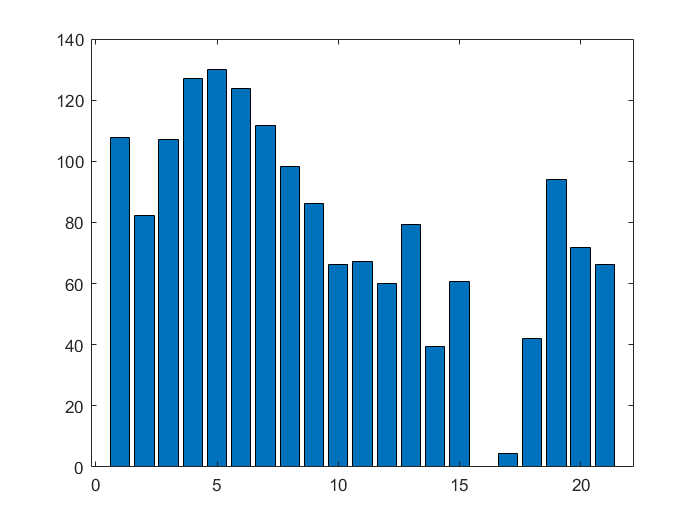

% compile kruppel and eve2
kruppel = [];
eve2 = [];
delay = 10;
for i = 1:length(trace_struct_final)
    if length(trace_struct_final(i).protein_interp) > 20
        kruppel = [kruppel trace_struct_final(i).protein_interp(1:end-delay)];
        eve2 = [eve2 trace_struct_final(i).fluo_interp(1 + delay:end)];
    end
end
bin_size = (max(kruppel) - min(kruppel)) / 20;
bin_counts = zeros(1, 21);
bin_vals = zeros(1,21);
for i = 1:length(kruppel)
    idx = floor(kruppel(i) / bin_size) + 1;
    bin_counts(idx) = bin_counts(idx) + 1;
    bin_vals(idx) = bin_vals(idx) + eve2(i);
end
figure();
bar(1:21, bin_vals ./ bin_counts);

Scatter plot of kruppel vs eve2 content (with given time delay)

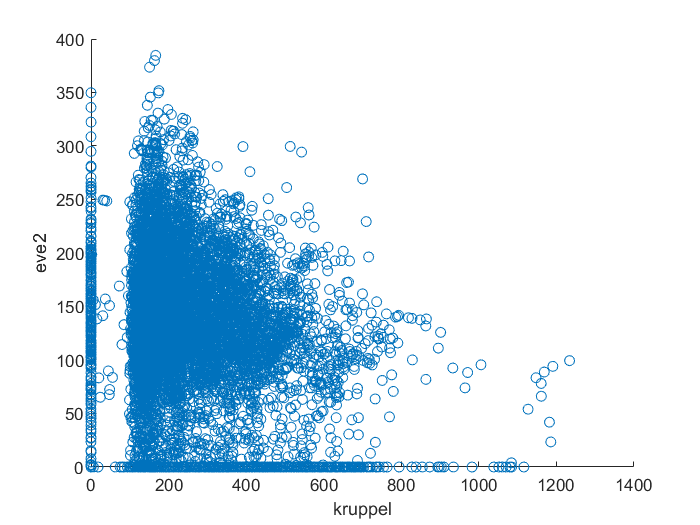

kruppel = [];
eve2 = [];
delay = 0;
for i = 1:length(trace_struct_final)
    if length(trace_struct_final(i).protein_interp) > 20
        kruppel = [kruppel trace_struct_final(i).protein_interp(1:end-delay)];
        eve2 = [eve2 trace_struct_final(i).fluo_interp(1 + delay:end)];
    end
end
figure();
scatter(kruppel,eve2);
xlabel('kruppel');
ylabel('eve2');

correlation_coeff = corrcoef(kruppel, eve2);
display(correlation_coeff);

correlation_coeff =     1.0000   -0.0853
   -0.0853    1.0000


Compares Kruppel content across time and ap bin in a scatter plot

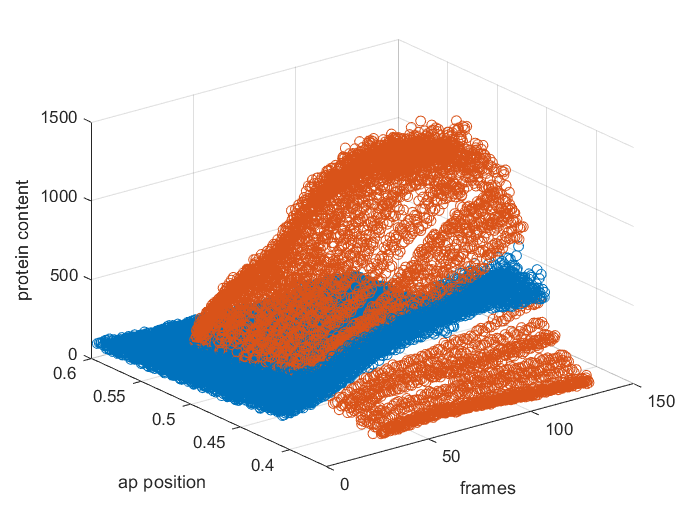

aps = [];
aps2 = [];
proteins = [];
proteins2 = [];
times = [];
times2 = [];
for i = 1:length(CompiledNuclei1)
    nuc = CompiledNuclei1(i);
    for j = 1:length(nuc.Frames)
        if ~isnan(nuc.FluoMax(j)) && nuc.nc == 14
            proteins = [proteins nuc.FluoMax(j)];
            aps = [aps nuc.MeanAP];
            times = [times nuc.Frames(j)];
        end
    end
end


for i = 1:length(CompiledNuclei2)
    nuc = CompiledNuclei2(i);
    for j = 1:length(nuc.Frames)
        if ~isnan(nuc.FluoMax(j)) && nuc.nc == 14
            proteins2 = [proteins2 nuc.FluoMax(j)];
            aps2 = [aps2 nuc.MeanAP];
            times2 = [times2 nuc.Frames(j)];
        end
    end
end
figure();
scatter3(times, aps, proteins);
hold on
scatter3(times2, aps2, proteins2);
xlabel('frames');
ylabel('ap position');
zlabel('protein content');

Quantifies variance in fluorescence (by nearest neighbor ap bin)

nns = 2:10;
vars = cell(1, length(nns));
nc14nucs1 = CompiledNuclei1([CompiledNuclei1.nc] == 14);
nc14nucs2 = CompiledNuclei2([CompiledNuclei2.nc] == 14);
for nn = nns
    for i = 1:length(nc14nucs1)
        if sum(isnan(nc14nucs1(i).FluoMax)) > 0
            continue
        end
        ap = nc14nucs1(i).MeanAP;
        first = nc14nucs1(i).Frames(1);
        last = nc14nucs1(i).Frames(end);
        diffs = abs([nc14nucs1.MeanAP] - ap);
        [B,I] = sort(diffs);
        k = 0;
        idx = 1;
        while k < nn && idx < length(nc14nucs1)
            idx1 = find(nc14nucs1(I(idx)).Frames == first);
            idx2 = find(nc14nucs1(I(idx)).Frames == last);
            if isempty(idx1) || isempty(idx2) || sum(isnan(nc14nucs1(I(idx)).FluoMax(idx1:idx2))) ~= 0
                idx = idx + 1;
                continue
            end
            k = k + 1;
            vars{nn - 1} = [vars{nn - 1} ... 
                (abs(nc14nucs1(I(idx)).FluoMax(idx1:idx2) - ...
                nc14nucs1(i).FluoMax) ./ ...
                min(nc14nucs1(I(idx)).FluoMax(idx1:idx2), ...
                nc14nucs1(i).FluoMax))'];
            idx = idx + 1;
        end
    end
    
    for i = 1:length(nc14nucs2)
        if sum(isnan(nc14nucs2(i).FluoMax)) > 0
            continue
        end
        ap = nc14nucs2(i).MeanAP;
        first = nc14nucs2(i).Frames(1);
        last = nc14nucs2(i).Frames(end);
        diffs = abs([nc14nucs2.MeanAP] - ap);
        [B,I] = sort(diffs);
        k = 0;
        idx = 1;
        while k < nn && idx < length(nc14nucs2)
            idx1 = find(nc14nucs2(I(idx)).Frames == first);
            idx2 = find(nc14nucs2(I(idx)).Frames == last);
            if isempty(idx1) || isempty(idx2) || sum(isnan(nc14nucs2(I(idx)).FluoMax(idx1:idx2))) ~= 0
                idx = idx + 1;
                continue
            end
            k = k + 1;
            vars{nn - 1} = [vars{nn - 1} ... 
                (abs(nc14nucs2(I(idx)).FluoMax(idx1:idx2) - ...
                nc14nucs2(i).FluoMax) ./ ...
                min(nc14nucs2(I(idx)).FluoMax(idx1:idx2), ...
                nc14nucs2(i).FluoMax))'];
            idx = idx + 1;
        end
    end
end

means = zeros(1, length(vars));
stds = zeros(1, length(vars));
for i = 1:length(vars)
    means(i) = mean(vars{i});
    stds(i) = std(vars{i});
end

figure();
errorbar(nns,means, stds);

Scatter plots nearest neighbor distance

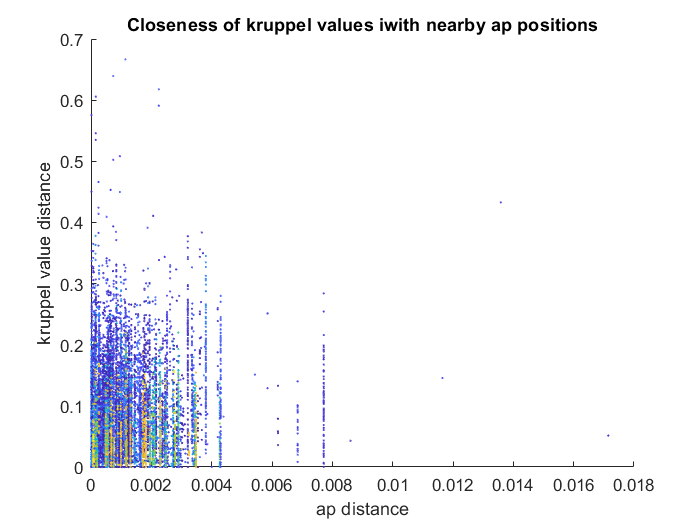

num_nearest = 1;
nns = cell(num_nearest);
aps = cell(num_nearest);
colors = cell(num_nearest);
nc14nucs1 = CompiledNuclei1([CompiledNuclei1.nc] == 14);
nc14nucs2 = CompiledNuclei2([CompiledNuclei2.nc] == 14);
nc14nucs = {nc14nucs1, nc14nucs2};
max_dist1 = [];
times1 = [];
max_dist2 = [];
times2 = [];
max_dist = 0;
for a = 1:length(nc14nucs)
    nc14nuc = nc14nucs{a};
    for i = 1:length(nc14nuc)
        ap = nc14nuc(i).MeanAP;
        prot = nc14nuc(i).FluoMax;
        diffs = abs([nc14nuc.MeanAP] - ap);
        [B,I] = sort(diffs);
        for j = 1:length(nc14nuc(i).Frames)
            if isnan(prot(j))
                continue
            end
            frame = nc14nuc(i).Frames(j);
            idx = 2;
            k = 1;
            while k <= length(nns) && idx <= length(diffs)
                nuc = nc14nuc(I(idx));
                idx1 = find(nuc.Frames == frame);
                if isempty(idx1) || isnan(nuc.FluoMax(idx1))
                    idx = idx + 1;
                    continue
                end
                dist = abs(nuc.FluoMax(idx1) - prot(j)) ...
                    / max(nuc.FluoMax(idx1), prot(j));
                if max_dist < dist && length(nuc.FluoMax) > 5 && length(prot) > 5
                    max_dist = dist;
                    max_dist1 = nuc.FluoMax;
                    times1 = nuc.Frames;
                    max_dist2 = prot;
                    times2 = nc14nuc(i).Frames;
                end
                nns{k} = [nns{k} dist];
                aps{k} = [aps{k} diffs(I(idx))];
                colors{k} = [colors{k} max(nuc.FluoMax(idx1), prot(j))];
                k = k + 1;
                idx = idx + 1;
            end
        end
    end
end
figure();
for i = 1:length(nns)
    scatter(aps{i}, nns{i}, 1, colors{i});
    hold on
end
xlabel('ap distance');
ylabel('kruppel value distance');
title('Closeness of kruppel values iwith nearby ap positions');

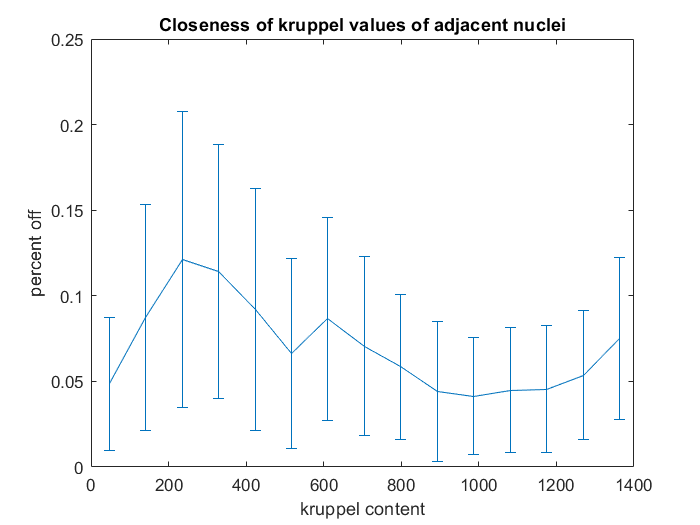


% looks at mean and std distance between adjacent nuclei, 
% binned according to kruppel content

num_bins = 15;
[Y,E] = discretize(colors{1}, num_bins);
means = zeros(1, num_bins);
stds = zeros(1, num_bins);
centers = zeros(1, num_bins);
for i = 1:num_bins
    points = nns{1}(Y == i);
    means(i) = mean(points);
    stds(i) = std(points);
    centers(i) = (E(i) + E(i + 1)) / 2;
end
figure();
errorbar(centers, means, stds);
ylabel('percent off');
xlabel('kruppel content');
title('Closeness of kruppel values of adjacent nuclei');

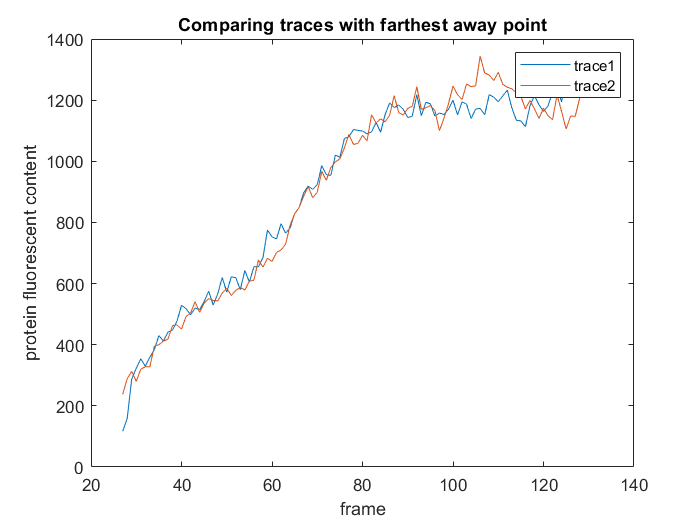


%finds adjacent nuclei that have furthest away kruppel 
% content from each other and plots them

figure();
plot(times1, max_dist1);
hold on
plot(times2, max_dist2);
title('Comparing traces with farthest away point');
xlabel('frame');
ylabel('protein fluorescent content');
legend('trace1', 'trace2');

scatter plot of slopes of kruppel content in eve2/kruppel data

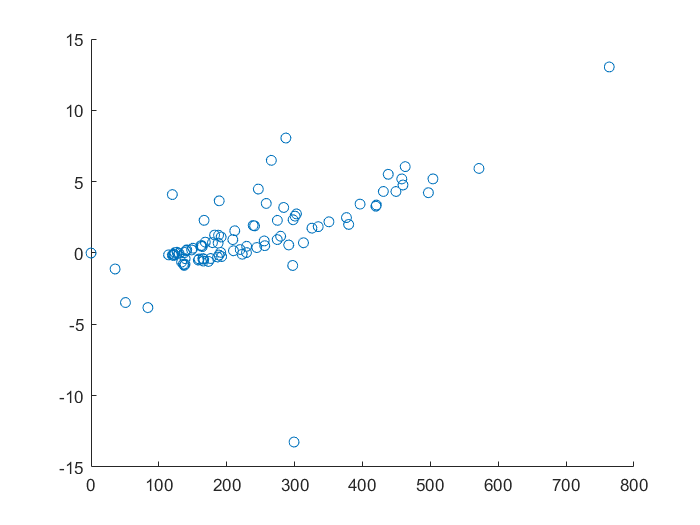

slopes = [];
means = [];
for i = 1:length(trace_struct_final)
    prot = trace_struct_final(i).protein_interp;
    times = trace_struct_final(i).time_interp;
    X = [times; ones(1,length(times))]';
    if length(prot) > 50
        slope = inv(X' * X) * X' * prot';
        slopes = [slopes slope];
        means = [means mean(prot)];
    end
end
scatter(means, slopes(1, 1:end) * 20);

Groups together traces by their start and end values

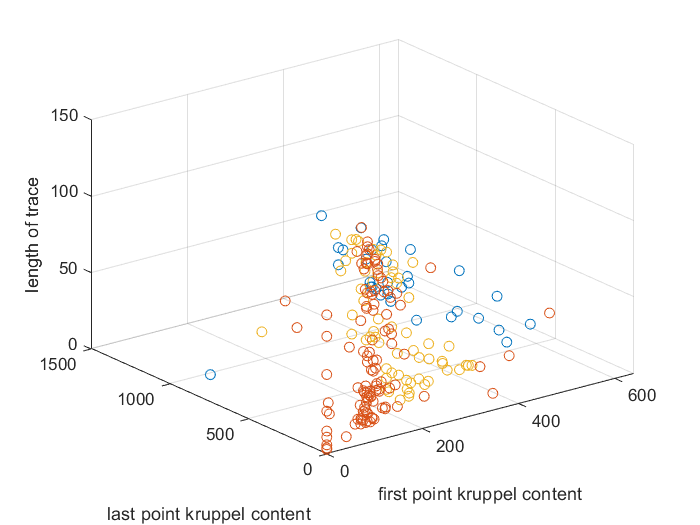

traces = [];
for i = 1:length(trace_struct_final)
    prot = trace_struct_final(i).protein_interp;
    traces = [traces; prot(1), prot(end), length(prot)];
end

idx = kmeans(traces, 3);
figure();
idxes = find(idx == 1);
scatter3(traces(idxes, 1), traces(idxes,2), traces(idxes,3));
hold on
idxes = find(idx == 2);
scatter3(traces(idxes, 1), traces(idxes, 2), traces(idxes, 3));
hold on
idxes = find(idx == 3);
xlabel('first point kruppel content');
ylabel('last point kruppel content');
zlabel('length of trace');
scatter3(traces(idxes, 1), traces(idxes, 2), traces(idxes, 3));

for i = 1:length(trace_struct_final)
    trace_struct_final(i).set = idx(i);
end
save('inference_by_krup_level', 'trace_struct_final');
